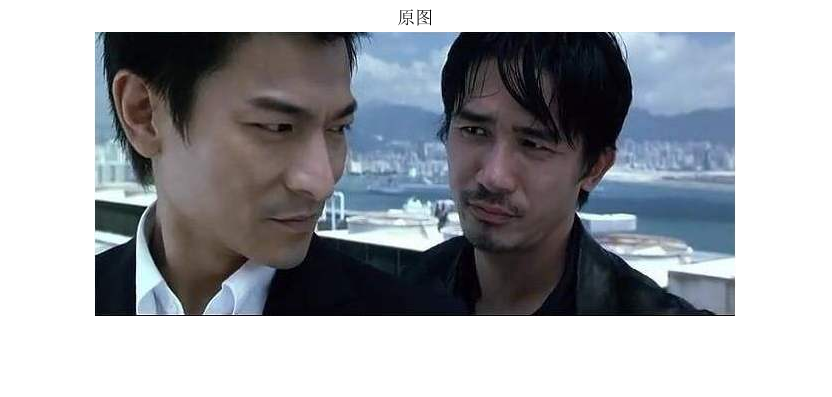

clc;clear;close all;
image=imread("07-刘德华.jpg");%读取图像
figure;
imshow(image);
title("原图");

im_r=image(:,:,1);

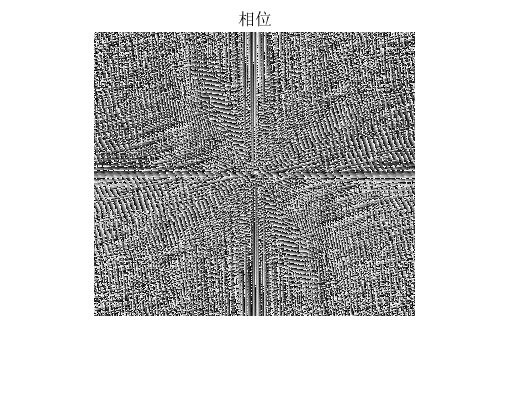


im_r_1=im_r(:,1:321);
Y1 = fft2(im_r_1);
Fc=fftshift(Y1); %将零频分量移到频谱中心
l=mat2gray(angle(Fc));%相位谱

figure;
imshow(l);
title("相位");

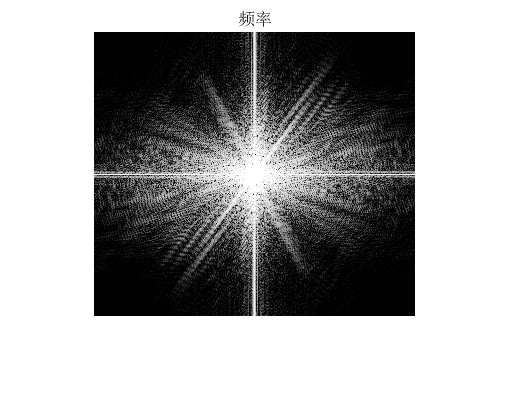


im_r_2=im_r(:,322:642);
Y2 = fft2(im_r_2);
Fc=fftshift(Y2); %将零频分量移到频谱中心

Fc=mat2gray(log(abs(Fc)));%取频率谱,进行对数增强
Fc=histeq(Fc);%直方图均衡化增强
Fc=imadjust(Fc,[0 1],[0 1],4);%幂律变换增强
l=mat2gray(Fc);%频率谱
figure;
imshow(l);
title("频率");

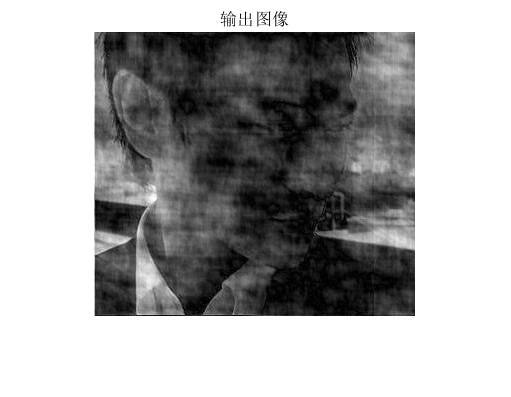

im_r_out=abs(Y2).*exp(angle(Y1)*1j);
im_r_out=ifft2(im_r_out);
im_r_out=mat2gray(abs(im_r_out));
figure;
imshow(im_r_out);
title("输出图像");